依赖[统一实验分析作图v17.2.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

根据PCA取模板细胞

DataSet=TransferLearning.FullCalcium;
PcaCalcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'统一PCA'),UniExp.Flags.log2FdF0,1:24,UniExp.Flags.Median));

PcaTable=UniExp.LinearPca(PcaCalcium.NTATS,4);

取PC1和 2 Coeff较小者排序在前5%的细胞

[~,SortIndex]=sort(min(PcaTable.Coeff(1:2,:),[],1),'descend');
CellUID=PcaCalcium.CellUID(SortIndex(1:uint8(end/20)));

HeatCalcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'TemplateHitMiss'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

HeatCalcium=HeatCalcium(ismember(HeatCalcium.CellUID,CellUID),:);

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1])

Colors =     0.0000    0.0000    1.0000
    1.0000    0.0000    0.0000
    0.0000    0.6809    0.0000


NtatsData=UniExp.HeatmapSort(HeatCalcium,"Learned_light_water").NTATS{:,:,["Learned_light_water","Transfer_audio_water_hit","Transfer_audio_water_miss"]};
SubTitles=["Learned light-water","Transfer audio-water hit","Transfer audio-water miss"];

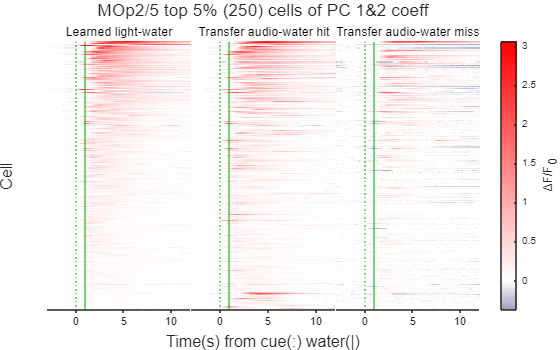

HeatmapLayout=TransferLearning.BasicHeatmap(NtatsData,SubTitles,Colors,false);
title(HeatmapLayout,sprintf('MOp2/5 top 5%% (%u) cells of PC 1&2 coeff',height(HeatCalcium)));
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('TemplateHitMiss.svg'),'-dsvg');

[Mean,Sem]=MATLAB.DataFun.MeanSem(NtatsData,1);
Xs=linspace(-3,12,size(Mean,2))';

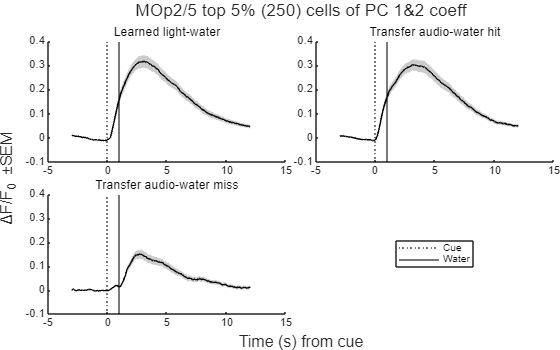

figure;
CurveLayout=tiledlayout(2,2,TileSpacing='tight',Padding='tight');
Axes=gobjects(3,1);
for A=1:3
	Axes(A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(Mean(:,:,A)',Sem(:,:,A)',X=Xs);
	CueLine=xline(0,':k');
	WaterLine=xline(1,'-k');
	title(SubTitles(A));
end
L=legend([CueLine,WaterLine],["Cue","Water"]);
L.Layout.Tile=4;
title(CurveLayout,sprintf('MOp2/5 top 5%% (%u) cells of PC 1&2 coeff',height(HeatCalcium)));
ylabel(CurveLayout,'ΔF/F_0 ±SEM');
xlabel(CurveLayout,'Time (s) from cue');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
MATLAB.UnifyYLims(Axes);
print(TransferLearning.ProjectPath('TemplateHitMissCurve.svg'),'-dsvg');